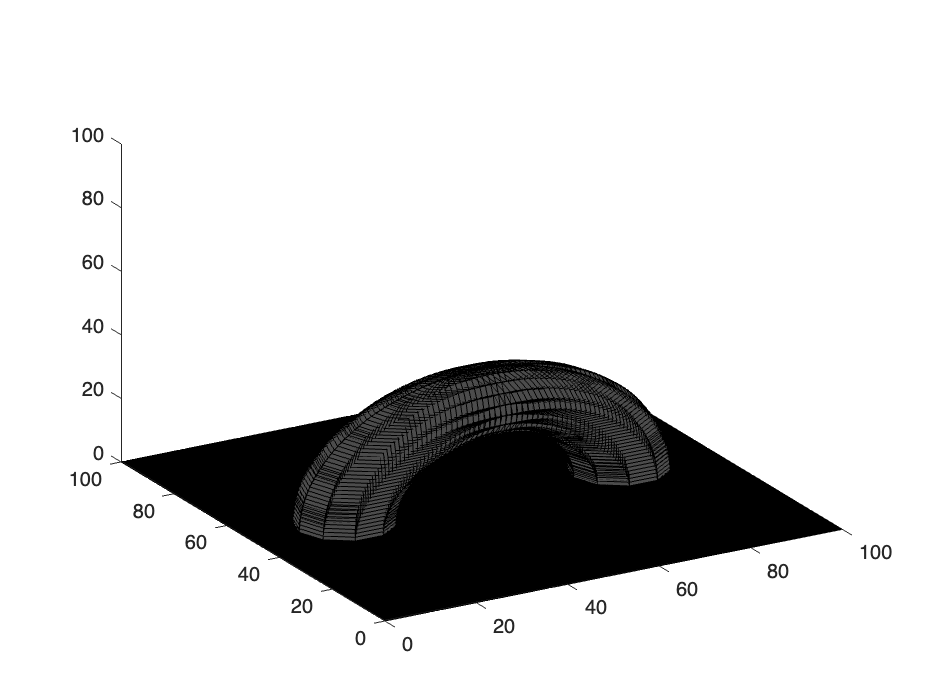

% Demonstration script for the 3D course planning software

% Create a new world and add an arch to it
space = world(100, 100, 100, Obstacle.empty);
space = add_arch(space, [50 50 0], 30, 80, 10);
plot_world(space);

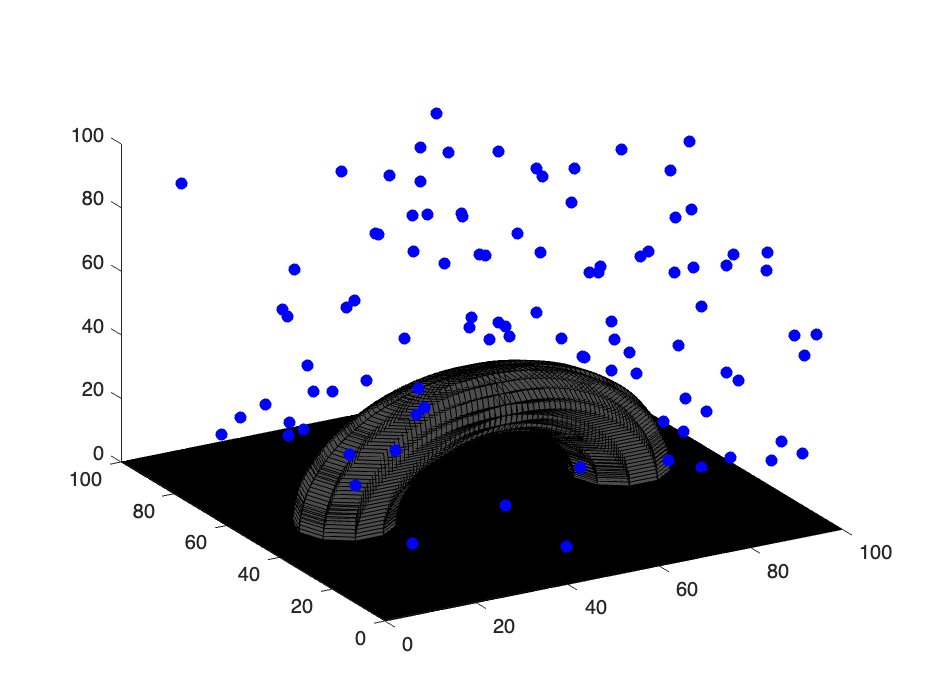


% Create a PRM planner over the space
planner = PRM(100, 10, space);

% Sample the space and populate the edges in the graph
planner = sampler(planner);
show_sample(planner);

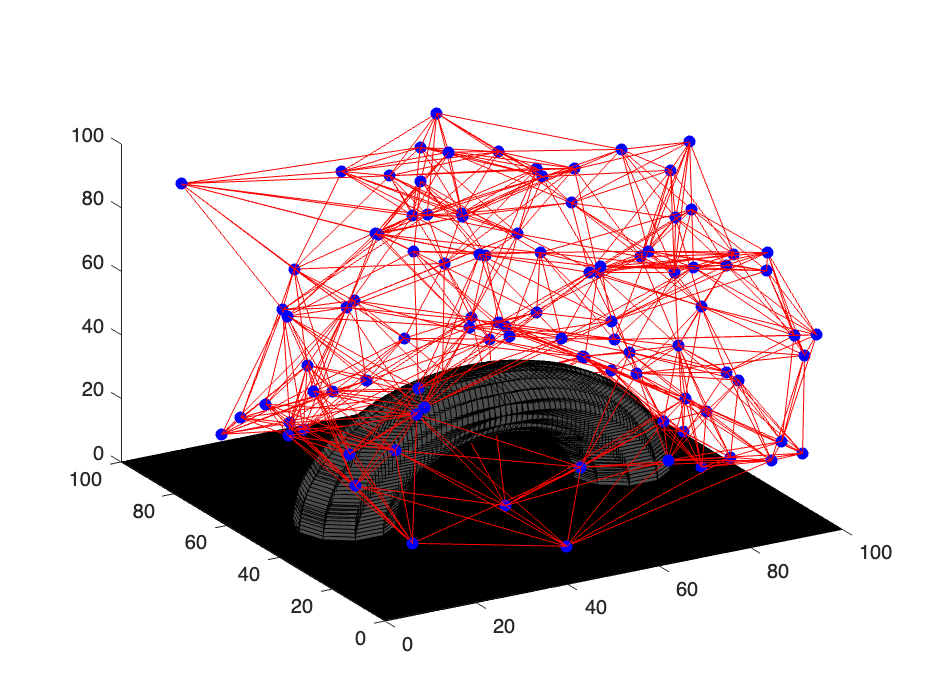

planner = create_edges(planner);
show_graph(planner)

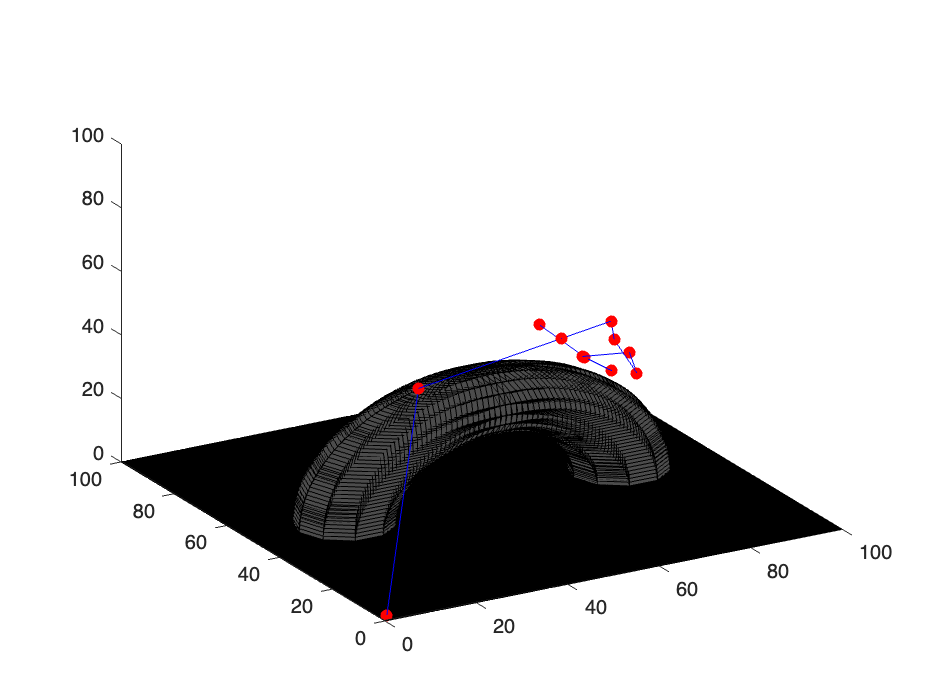


% Now make a copy of the planner in which we have solved for a path
start = [1 1 1];
goal = [80 80 30];
mapped = find_path(planner, start, goal);

% Show the path
show_path(mapped);

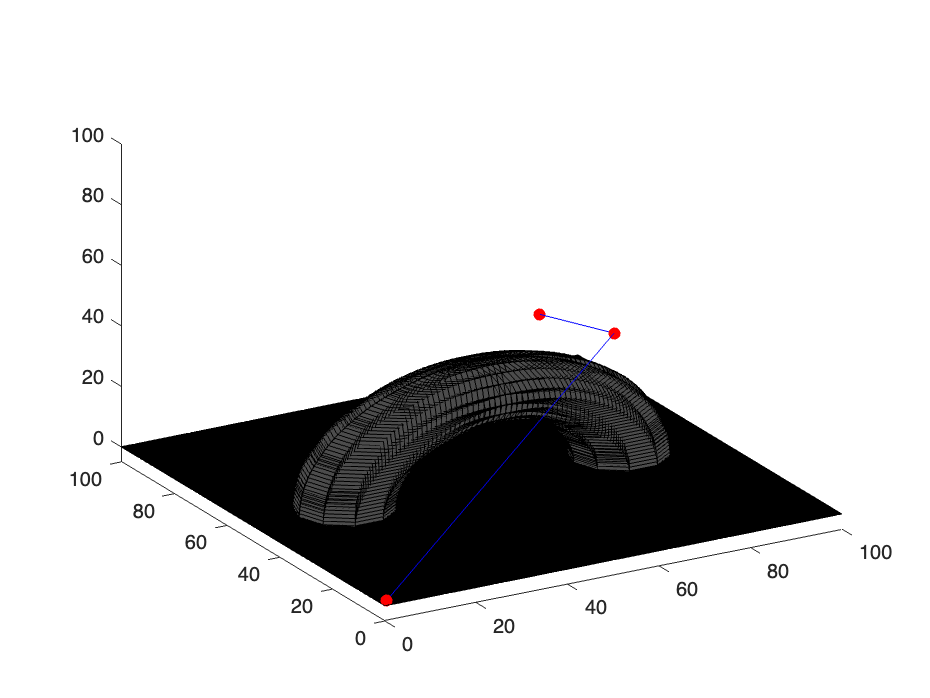


% Do post-processing
mapped = post_process(mapped);
show_path(mapped);